%{
This notebook aims to understand the lithium loss (LLI) during formation, which
is required to initially align the half-cell voltage traces to the full
cell voltage trace (since data comes from separate sources, rather than a
3-electrode cell)

The LLI is output at the end of the script, in terms of mAh/g of LFP
cathode

Note that the result has one caveat - the shape of the half-cell curves
was unable to be matched to the full cell that was taken from She, Uceda,
and Pope's paper (see /data/README.md for more details on this dataset), so
the best guess of formation LLI was used
%}

% Load anode data
tableN = readtable("si_anode2.csv");
cVecN = table2array(tableN(:,"capacity"));
vVecN = table2array(tableN(:,"voltage"));

[thetaVecN, vThetaVecN] = normalizeCapacity(cVecN, vVecN);

% Load cathode data
tablePLFP = readtable("lfp_cathode.csv");
cVecP = table2array(tablePLFP(:,"capacity"));
vVecP = table2array(tablePLFP(:,"voltage"));

[thetaVecP, vThetaVecP] = normalizeCapacity(cVecP, vVecP);

% Load full cell data
tableFullLFP = readtable("full_cell_cover2_discharge.csv");
cVecFull = table2array(tableFullLFP(:,"capacity"));
vVecFull = table2array(tableFullLFP(:,"voltage"));

%plot(thetaVecN, vThetaVecN, 'r--', thetaVecP, vThetaVecP, 'b--')
%plot(cVecFull, vVecFull, 'k')

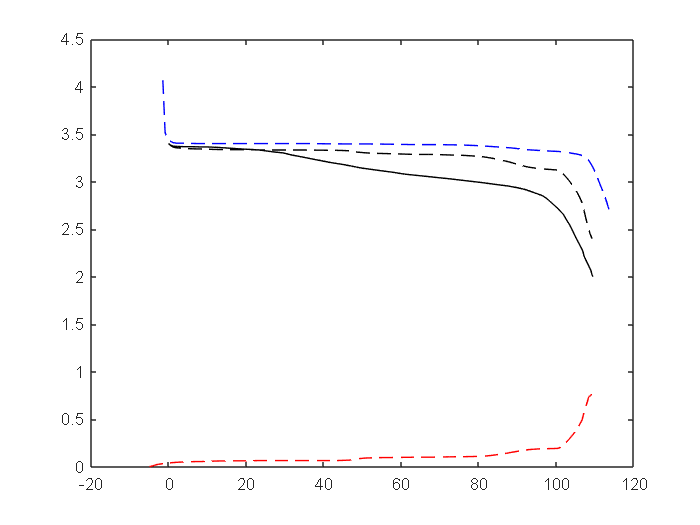

% Set fitting parameters
chargeDir = "dchg";
vMax = 3.4;
vMin = 2.4;
cN = 115;
cP = 115;
x0 = 0;
y0 = 0.97;

% Calculate modelled full cell curve
[cVecNModel, vVecNModel, cVecPModel, vVecPModel, cVecFullModel, vVecFullModel] = ...
    combineHalfCells(thetaVecN, vThetaVecN, thetaVecP, vThetaVecP, cN, cP, x0, y0, vMin, vMax, chargeDir);

% Compared modelled full cell and actual full cell data in a plot
plot(cVecFullModel, vVecFullModel, 'k--', cVecFull, vVecFull, 'k', ...
    cVecPModel, vVecPModel, 'b--', cVecNModel, vVecNModel, 'r--')

% Output the LLI due to formation
formationLLI = (1-y0)*cN-x0*cN;
fprintf("Formation LLI is %d mAh/g LFP", formationLLI)

Formation LLI is 3.450000e+00 mAh/g LFP